%% ========================================================================
%  SIM_05_LeaderFailure_SwarmReconfig
%  --------------------------------------------------------------
%  - Simulates 5-satellite swarm where central leader fails mid-mission.
%  - Remaining 4 satellites reconfigure into a new cross formation.
%  - Leader holds its position (no control), others minimize DeltaV.
%  - Trajectory and DeltaV plots are generated.
%
%  Author: Sabrina Nicacio
% ========================================================================

clc; clear; close all;

%% === ORBIT PARAMETERS ===
mu = 3.986e14;
Re = 6371e3;
alt = 500e3;
a = Re + alt;
n = sqrt(mu / a^3);

T = 2*pi / n;
N_orbits = 1;
dt = 10;
N = round(N_orbits * T / dt);
t_vec = (0:N-1)*dt;

%% === SYSTEM MATRICES ===
A = [  0     0     0     1     0     0;
       0     0     0     0     1     0;
       0     0     0     0     0     1;
     3*n^2   0     0     0   2*n     0;
       0     0     0  -2*n     0     0;
       0     0  -n^2    0     0     0];

B = [zeros(3); eye(3)];

%% === INITIAL STATES ===
x0_list = {
    [0; 100; 0; 0; 0.1; 0],      % Sat 1 - Leader (failed)
    [0; -120; 40; 0; -0.08; 0],  % Sat 2
    [30; 80; -50; 0; 0.05; 0],   % Sat 3
    [-50; -90; 20; 0; -0.1; 0],  % Sat 4
    [60; 0; -30; 0; 0; 0]        % Sat 5
};

% Sat 1 fails — remains at its final position (hold)
leader_index = 1;
x_leader_final = [0; 0; 0; 0; 0; 0];  % stays at original center target

% New formation avoids center
target_list = {
    x_leader_final,                 % Sat 1: stays still
    [50; 0; 0; 0; 0; 0],            % Sat 2: right
    [-50; 0; 0; 0; 0; 0],           % Sat 3: left
    [0; 50; 0; 0; 0; 0],            % Sat 4: up
    [0; -50; 0; 0; 0; 0]            % Sat 5: down
};

num_sats = 5;
X = cell(num_sats, 1);
U = cell(num_sats, 1);
dV_total = zeros(num_sats, 1);

%% === CVX CONTROL FOR 4 SATELLITES (SKIP LEADER) ===
for i = 1:num_sats
    x0 = x0_list{i};
    x_target = target_list{i};
    
    if i == leader_index
        % Simulate passive drift (no control)
        cw_dynamics = @(t, x) A * x;
        [~, x_traj] = ode45(cw_dynamics, linspace(0, N*dt, N), x0);
        X{i} = x_traj';
        U{i} = zeros(3, N-1);
        dV_total(i) = 0;
    else
        cvx_begin quiet
            variables x(6, N) u(3, N-1)
            minimize( sum(norms(u, 2, 1)) )
            subject to
                x(:,1) == x0;
                x(:,N) == x_target;
                for k = 1:N-1
                    x(:,k+1) == x(:,k) + dt * (A * x(:,k) + B * u(:,k));
                end
        cvx_end
        X{i} = x;
        U{i} = u;
        dV_total(i) = sum(vecnorm(u, 2, 1));
    end
end

%% === TOTAL DELTAV TABLE ===
sat_IDs = (1:num_sats)';
T_dV = table(sat_IDs, dV_total, ...
    'VariableNames', {'Satellite', 'DeltaV'});
disp(' ');

disp('==== Total DeltaV per Satellite ====');

==== Total DeltaV per Satellite ====


disp(T_dV);

    Satellite     DeltaV 
    _________    ________

        1               0
        2         0.41161
        3         0.30244
        4        0.067024
        5         0.21239



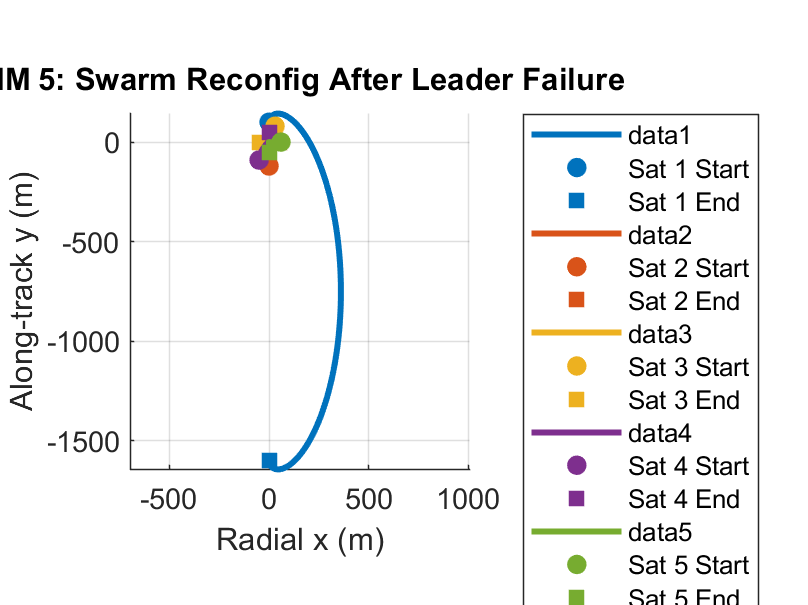


%% === PLOT 1: TRAJECTORY PLOT ===
colors = lines(num_sats);
figure; hold on;
for i = 1:num_sats
    x = X{i};
    plot(x(1,:), x(2,:), 'Color', colors(i,:), 'LineWidth', 2);
    plot(x(1,1), x(2,1), 'o', 'Color', colors(i,:), ...
        'MarkerFaceColor', colors(i,:), 'DisplayName', ['Sat ' num2str(i) ' Start']);
    plot(x(1,end), x(2,end), 's', 'Color', colors(i,:), ...
        'MarkerFaceColor', colors(i,:), 'DisplayName', ['Sat ' num2str(i) ' End']);
end
xlabel('Radial x (m)');
ylabel('Along-track y (m)');
title('SIM_ 5: Swarm Reconfig After Leader Failure');
legend('Location', 'bestoutside');
grid on; axis equal;
saveas(gcf, 'SIM_05_LeaderFailure_Traj.png');

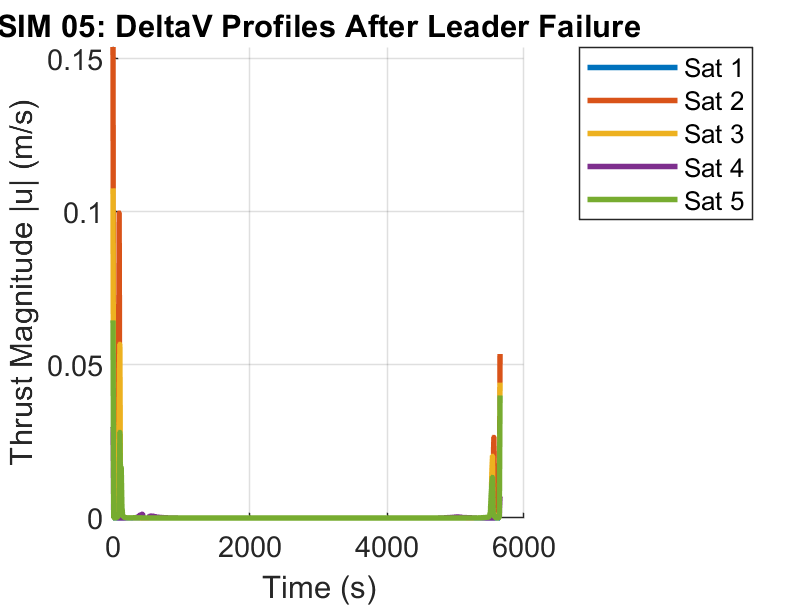


%% === PLOT 2: DELTAV PROFILES ===
figure; hold on;
for i = 1:num_sats
    u = U{i};
    dV = vecnorm(u, 2, 1);
    plot(t_vec(1:end-1), dV, 'LineWidth', 1.8, 'Color', colors(i,:), ...
        'DisplayName', ['Sat ' num2str(i)]);
end
xlabel('Time (s)');
ylabel('Thrust Magnitude |u| (m/s)');
title('SIM 05: DeltaV Profiles After Leader Failure');
legend('Location', 'bestoutside');
grid on;
saveas(gcf, 'SIM_05_LeaderFailure_DeltaV.png');


%% === TOTAL DELTAV TABLE ===
sat_IDs = (1:num_sats)';
T_dV = table(sat_IDs, dV_total, ...
    'VariableNames', {'Satellite', 'Total_DeltaV_m_per_s'});
disp(' ');

disp('==== Total DeltaV per Satellite ====');

==== Total DeltaV per Satellite ====


disp(T_dV);

    Satellite    Total_DeltaV_m_per_s
    _________    ____________________

        1                     0      
        2               0.41161      
        3               0.30244      
        4              0.067024      
        5               0.21239      





%% === END ===
disp('Simulation completed: SIM_05_LeaderFailure_SwarmReconfig');

Simulation completed: SIM_05_LeaderFailure_SwarmReconfig
